# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
numOfLines = 6;
threshold = 0.5;

## Generate a random physical topology

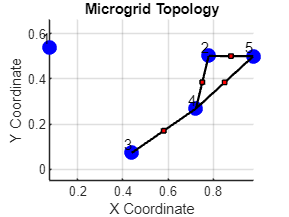

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     0     0     0
     0     0     0     1     1
     0     0     0     1     0
     0    -1    -1     0     1
     0    -1     0    -1     0

B_il Matrix:
     0     0     0     0
     1     1     0     0
     0     0     1     0
    -1     0    -1     1
     0    -1     0    -1



coords =     0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999


adjMatrix =      0     0     0     0     0
     0     0     0     1     1
     0     0     0     1     0
     0    -1    -1     0     1
     0    -1     0    -1     0


B_il =      0     0     0     0
     1     1     0     0
     0     0     1     0
    -1     0    -1     1
     0    -1     0    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.

[coords, adjMatrix, B_il] = GenerateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0);
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     3.4461   11.1102   -3.6734
   11.1102   65.0727  -11.9587
   -3.6734  -11.9587   13.2337


KVal =  -191.5525   11.2436   -3.8947


LVal =  -148.1302   21.4087  -22.0662


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3078   10.8910   -3.5623
   10.8910   65.1061  -11.8481
   -3.5623  -11.8481   13.0642


KVal =  -161.0809   11.7778   -3.8909


LVal =  -129.9164   18.4589  -18.9823


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4649   11.1324   -3.6874
   11.1324   65.0377  -11.9732
   -3.6874  -11.9732   13.2548


KVal =  -146.9838   11.5819   -3.9364


LVal =  -113.3440   16.4560  -16.9638


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4851   11.1750   -3.7050
   11.1750   65.0786  -11.9888
   -3.7050  -11.9888   13.2816


KVal =  -120.2811   11.9949   -3.9745


LVal =   -92.7848   13.5461  -13.9548


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3007   10.8670   -3.5547
   10.8670   65.0547  -11.8419
   -3.5547  -11.8419   13.0524


KVal =  -130.4599   11.3147   -3.7939


LVal =  -105.4621   14.9841  -15.4182


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0403

nuBarVal = -100.0000

rhoBarVal = 0.0707

status = logical
   1


PBarVal = 0.0424

nuBarVal = -100.0000

rhoBarVal = 0.0800

status = logical
   1


PBarVal = 0.0526

nuBarVal = -100.0000

rhoBarVal = 0.0796

status = logical
   1


PBarVal = 0.0429

nuBarVal = -100.0000

rhoBarVal = 0.1043

status = logical
   1


PBarVal = 0.0392

nuBarVal = -100.0000

rhoBarVal = 0.0919

status = logical
   1


PBarVal = 0.0399

nuBarVal = -100.0000

rhoBarVal = 0.0847

status = logical
   1



% R_DG{i} vs DG{i}.R

Clear variables unrelated

clearvars -EXCEPT DG Line numOfDGs numOfLines

## Centralized Local Controller Design

[DG,Line] = centralizedLocalControlDesign(DG,Line,B_il) % topologyMetrics may be the B matrix 

Unrecognized function or variable 'B_il'.

% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 